计算等离子体频率时间调制的能带结构

作者：FTT

创建时间：2024.11.24

clear
clc
close all

定义参数

omega_r0 = 1;     % 共振频率
omega_m = 2 * 0.95 * omega_r0;      % 调制频率
gamma = 0;        % 阻尼因子
m = 0.2;         % 调制强度
omega_p0 = 3.5 * omega_r0;   % 等离子体频率
c = 3e8;          % 光速
k_r0 = omega_r0 / c;
N = 1;           % 展开阶数（从-N到N）

定义频率范围

omega = 0:omega_m/10000:N*omega_m;

计算静态极化率


$$\chi(\omega)=\frac{\omega^{2}_{p}}{\omega^{2}_{r0}-\omega^{2}+j\gamma\omega}$$


chi = @(w) omega_p0 ^ 2 ./ (omega_r0 ^ 2 - w .^ 2 + 1i * gamma * w);

构建大型矩阵以包含多个谐波

n_total = 2 * N + 1;
K = zeros(length(omega), n_total); % 动量

扫频填充矩阵元素，并计算特征值


$$Me=k^{2}c_{0}^{2}e$$


loop = 1;
for omega_ = omega
    M = zeros(n_total, n_total);

    % 填充矩阵元素
    for i = -N:N
        for j = -N:N
            idx_i = i + N + 1; % 谐波次数在矩阵中的位置
            idx_j = j + N + 1; % 谐波次数在矩阵中的位置
            omega_n = @(n) omega_ + n * omega_m; % 谐波频率

            % 对角项
            if i == j
                M(idx_i, idx_j) = (1 + chi(omega_n(i))) * omega_n(i) ^ 2;
            
            % 上次对角项
            elseif i - j == -1
                M(idx_i, idx_j) = m / 2 * chi(omega_n(i + 1)) * omega_n(i) ^ 2;

            % 下次对角项
            elseif i - j == 1
                M(idx_i, idx_j) = m / 2 * chi(omega_n(i - 1)) * omega_n(i) ^ 2;
            end
        end
    end

    % 计算特征值和波数
    eigvalue = eig(M)';
    K(loop, :) = sqrt(eigvalue) / c;
    % K(loop, :) = sort(K(loop, :));

    loop = loop + 1;
end
K(real(K)==0) = NaN;

计算两个未调制介质的色散关系


$$\omega_{p1}^{2}=\omega_{p0}^{2}(1-m/2)\\
\omega_{p2}^{2}=\omega_{p0}^{2}(1+m/2)$$


k1 = omega / c .* sqrt(1 + chi(omega) * (1 - m /2));
k2 = omega / c .* sqrt(1 + chi(omega) * (1 + m /2));
k1(real(k1)==0) = NaN;
k2(real(k2)==0) = NaN;

绘制色散关系

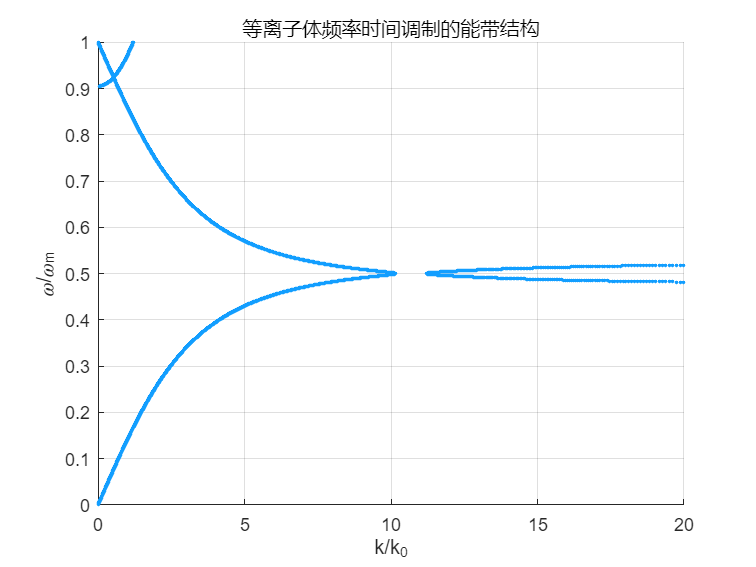

figure;
hold on;
plot(real(K') / k_r0, omega / omega_m, '.', 'Color', [0.07,0.62,1.00])
xlabel('k/k_r_0')
ylabel('\omega/\omega_m')
title('等离子体频率时间调制的能带结构')
grid on
xlim([0 20])

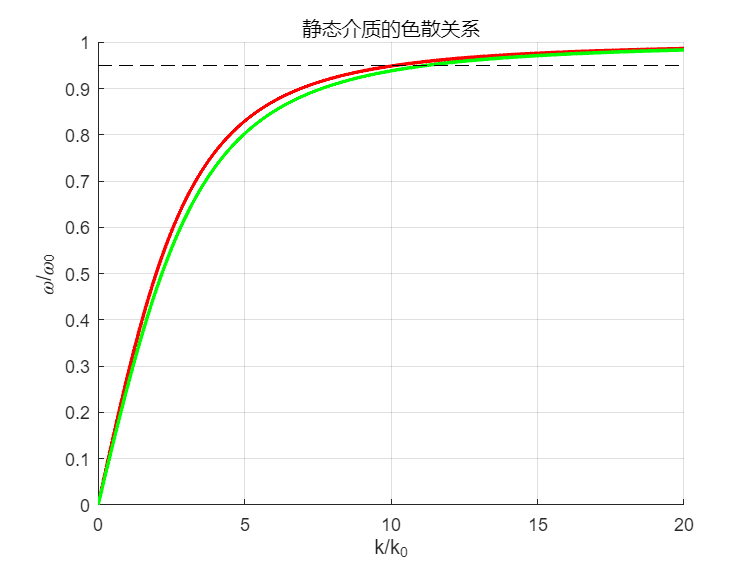

figure;
hold on
plot(real(k1) / k_r0, omega / omega_r0, 'r-', 'LineWidth', 2)
plot(real(k2) / k_r0, omega / omega_r0, 'g-', 'LineWidth', 2)
plot([0, 20], [omega_m / 2 / omega_r0, omega_m / 2 / omega_r0], 'k--')
xlabel('k/k_r_0')
ylabel('\omega/\omega_r_0')
title('静态介质的色散关系')
grid on
xlim([0 20])